%apply adaptive filter on e and f
clf;

load('djia.mat')

p = 3; % week 3
NN = 520;

% Defining X of the last decade
for i = 1:NN-p
    for j = 1:p
        X(i,j) = djia(4342+i+j-1);
    end
end

% Defining x
for i = p+1:NN
    x(i-p,1) = djia(i);
end

% Solve for coefficients using X and x
%a = -X\x;
%xhat1 = -X*a;

%disp(X)

n = ceil(numel(X)/2)

n = 776

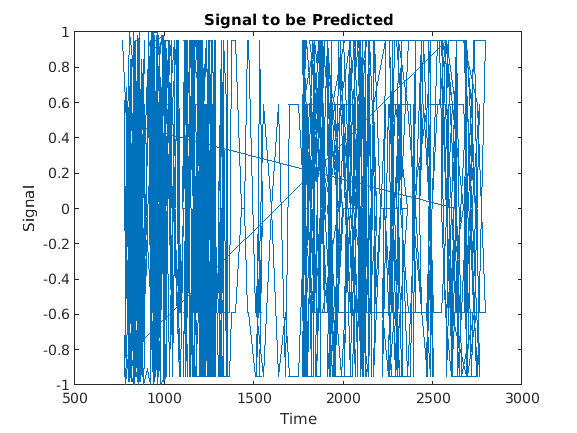


time1 = X(1:n);
time2 = X(n+1:end);
time = [time1 time2];

signal = [sin(time1*4*pi) sin(time2*8*pi)];
plot(time, signal)
xlabel('Time');
ylabel('Signal');
title('Signal to be Predicted');

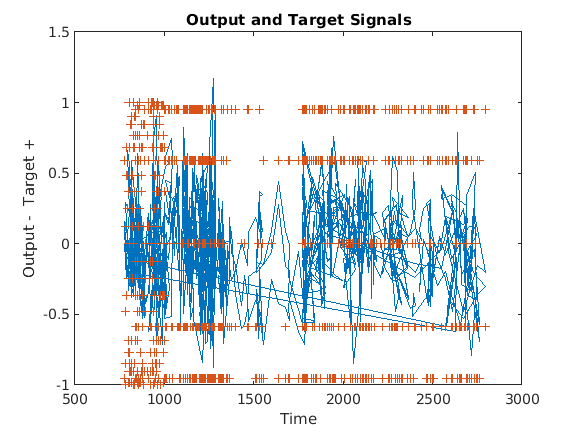


% converts signal to array
signal = con2seq(signal);

Xi = signal(1:4); % initial input delay states
X2 = signal(4:end);
timex = time(4:end);

% targets match the inputs using the last 5 values
T = signal(4:end);

 % creates linear layer with 1 neuron
net = linearlayer(1:4,0.1);
view(net)

[net,Y] = adapt(net,X2,T,Xi);

% output signal with targets plotted
figure
plot(timex,cell2mat(Y),timex,cell2mat(T),'+')
xlabel('Time');
ylabel('Output -  Target +');
title('Output and Target Signals');

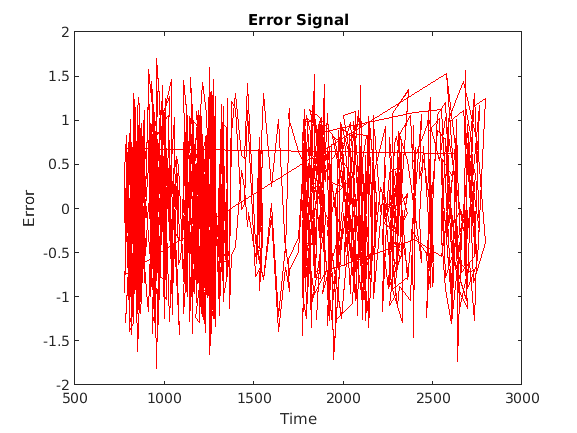


% plotted error
figure
E = cell2mat(T)-cell2mat(Y);
plot(timex,E,'r')
hold off
xlabel('Time');
ylabel('Error');
title('Error Signal');

xhat_u = max(timex)/timex(1);
upper_bound = 1000*xhat_u;
txt1 = ['Based on our prediction, in 520 weeks we will have ',...
num2str(upper_bound)];
disp(txt1)

Based on our prediction, in 520 weeks we will have 3612.4492


lower_bound = 1000*(1+0.03/52)^520;
txt4 = [' Within 520 weeks with 3% the minimal amount we can make is ',...
num2str(lower_bound)];
disp(txt4)

 Within 520 weeks with 3% the minimal amount we can make is 1349.742


lower_bound2 = 1000*timex(end)/timex(1);
txt2 = [' If we were to buy and hold, using $1000 we would yeild ',...
num2str(lower_bound2)];
disp(txt2)

 If we were to buy and hold, using $1000 we would yeild 3394.589


rr = ((timex(end)/timex(1))^(1/NN)-1)*52;
txt3 = ['To have the same, the APR rate should be ',num2str(rr*100),'%'];
disp(txt3)

To have the same, the APR rate should be 12.2362%


Analysis:

Compared to the moving-average filter, the graphs were probably not as accurate for the adaptive filter. The signal graphs and the error graphs on the adaptive filter were very off comapred to the moving-average filter. So, for this particular example, the adaptive filter was not optimal and it did not yield better results, However, the prediction results, despite the bad graphs, yielded better results in general. Compared to the moving-average filter, the results for maximum amount of money made were higher at $3,612, buy and hold was higher at $3,394 and APR rate was higher at 12.2361% compared to $2395, $2223, and 7.9953%, respectively. Of course, the minimal amuont was the same since it was the same equation. In terms of amount of money, it looks like the adaptive filter was better, but that does not mean it was more accurate. 